clc;
clear;
runtime=80

runtime = 80

for count=1:runtime
Road_length  =100;
car_number   = count;
N(count)=car_number
acceleration = 6;
deceleration =-6.5;
density(count) = car_number/Road_length;
%initial speed
u = 5;
%time limitis
time =1000;
%limit speed
lim = 15;

%repeat loop
for l=1:20
%initial position of car
J = 1:car_number;
A = rand(1,car_number).*Road_length;
x(J,1) =sort(A);
v(J,1)=u;
%minimum distance between cars
x0 = Road_length/car_number;
num = car_number-1;
delT = 0.1;
k = time / delT;
%
average(1) = 0;
t(1) = 0;

for T=2:k
    for J=1:car_number
        if J == car_number
            if J==1
                dis(J,T)= Road_length;
            else
                dis(J,T) = x(1,T-1)-x(J,T-1);
            end
        else
            dis(J,T) = x(J+1,T-1)-x(J,T-1);
        end
        if dis(J,T)<0
            dis(J,T) = Road_length+dis(J,T);
        end
        if dis(J,T) > acceleration * delT
           v(J,T)=v(J,T-1) + acceleration * delT;
        elseif dis(J,T) <= v(J,T-1)
            dis(J,T)=0;
            v(J,T)=0;
        else
           v(J,T)=v(J,T-1)+ deceleration * delT;
        end
        if v(J,T)<0
            v(J,T)=0;
        end
        if v(J,T)>lim
            v(J,T)=lim;
        end
        delta_dis(J,T)=v(J,T)*delT;
        if delta_dis(J,T)>dis(J,T);
            delta_dis(J,T)=dis(J,T);
            v(J,T)=dis(J,T);
        end
        x(J,T)=x(J,T-1)+delta_dis(J,T);
        if x(J,T) > Road_length
           x(J,T)=x(J,T)- Road_length;
        end
    end
      max_speed(T) = max(v(J,T));
      min_speed(T) = min(v(J,T));
      average(T) = sum(v(:,T)) / car_number;
      t(T) = t(T-1) + delT;
end
t(T) = t(T);
x(J,T)=x(J,T);
v(J,T)=v(J,T);
average(T) = average(T);
k_1 = floor(k/2);
d_av = average(1,(k_1):k);
m(l) = mean(d_av);
end
S(count)=std(m);
averagespeed(count) = mean(m);
acc(count)=acceleration;
%percentage
end

N = 1

N =      1     2


N =      1     2     3


N =      1     2     3     4


N =      1     2     3     4     5


N =      1     2     3     4     5     6


N =      1     2     3     4     5     6     7


N =      1     2     3     4     5     6     7     8


N =      1     2     3     4     5     6     7     8     9


N =      1     2     3     4     5     6     7     8     9    10


N =      1     2     3     4     5     6     7     8     9    10    11


N =      1     2     3     4     5     6     7     8     9    10    11    12


N =      1     2     3     4     5     6     7     8     9    10    11    12    13


N =      1     2     3     4     5     6     7     8     9    10    11    12    13    14


N =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15


N =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16


N =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17


N =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18


N =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19


N =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20


N =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21


N =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22


N =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23


N =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24


N =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25


N =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26


N =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27


N =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28


N =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29


N =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


N =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31


N =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32


N =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33


N =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34


N =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35


N =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36


N =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37


N =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38


N =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39


N =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40


N =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41


N =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42


N =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43


N =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44


N =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45


N =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46


N =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47


N =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48


N =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


N =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


N =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


N = 1×52
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


N = 1×53
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


N = 1×54
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


N = 1×55
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


N = 1×56
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


N = 1×57
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


N = 1×58
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


N = 1×59
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


N = 1×60
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


N = 1×61
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


N = 1×62
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


N = 1×63
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


N = 1×64
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


N = 1×65
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


N = 1×66
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


N = 1×67
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


N = 1×68
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


N = 1×69
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


N = 1×70
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


N = 1×71
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


N = 1×72
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


N = 1×73
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


N = 1×74
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


N = 1×75
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


N = 1×76
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


N = 1×77
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


N = 1×78
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


N = 1×79
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


N = 1×80
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


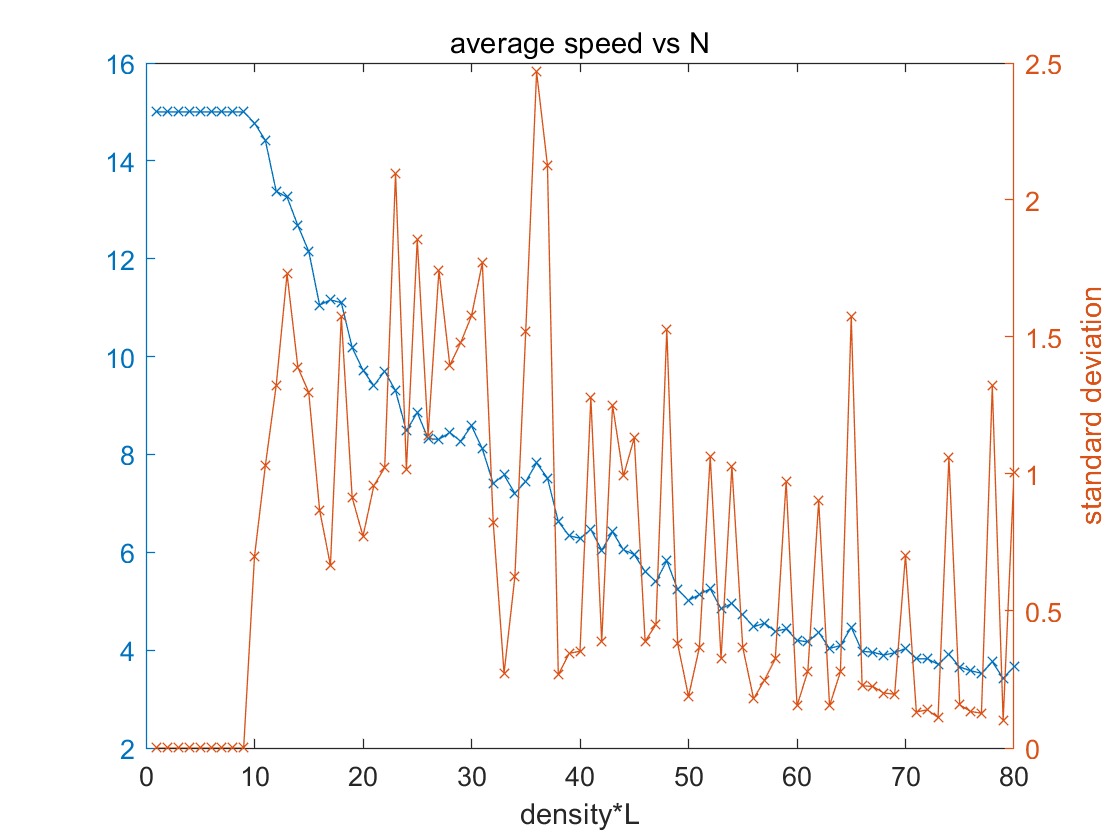

yyaxis left
plot(N,averagespeed,"-x","MarkerSize",5)

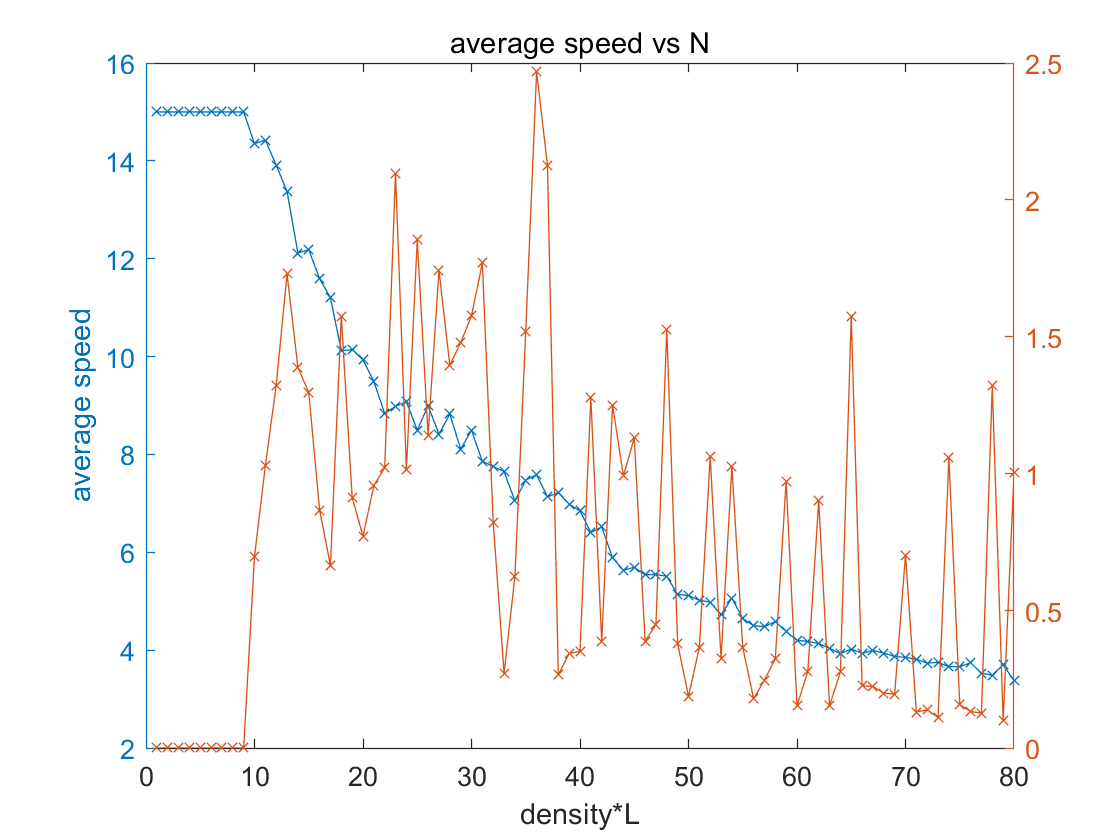

title("average speed vs N") 
xlabel('density*L')
ylabel('average speed')

yyaxis right
plot(N,S,"-x","MarkerSize",5)

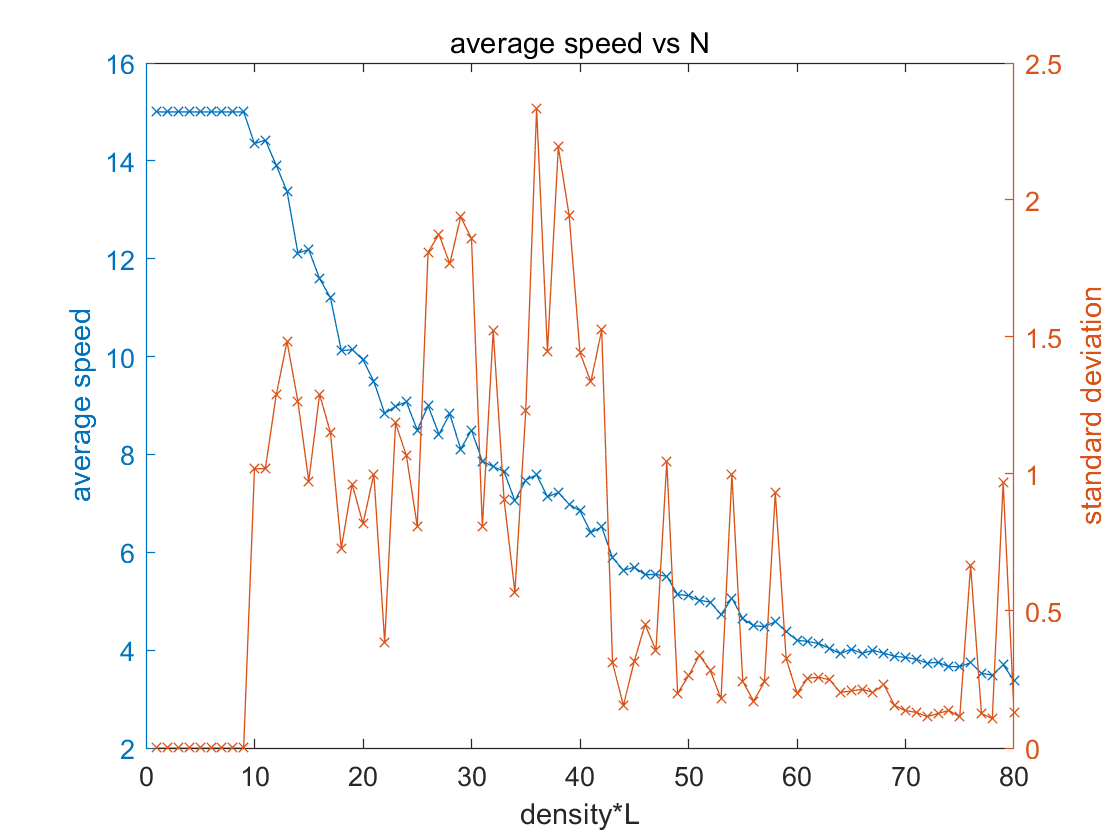

ylabel('standard deviation')

hold on
smootheData
hold off

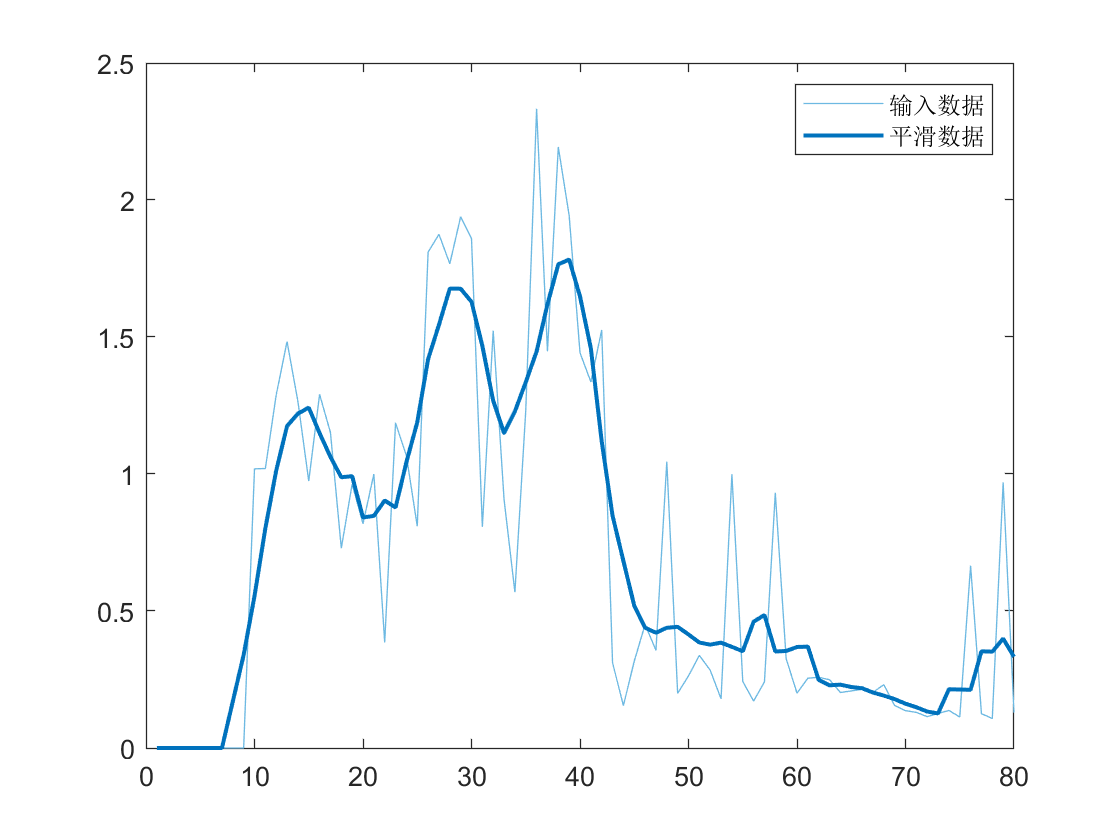

% 对输入数据进行平滑处理
smoothedData = smoothdata(S,'movmean','SmoothingFactor',0.25);

% 显示结果
clf
plot(S,'Color',[109 185 226]/255,'DisplayName','输入数据')
hold on
plot(smoothedData,'Color',[0 114 189]/255,'LineWidth',1.5,'DisplayName','平滑数据')
hold off
legend